# 第一问线性规划

变量初始化

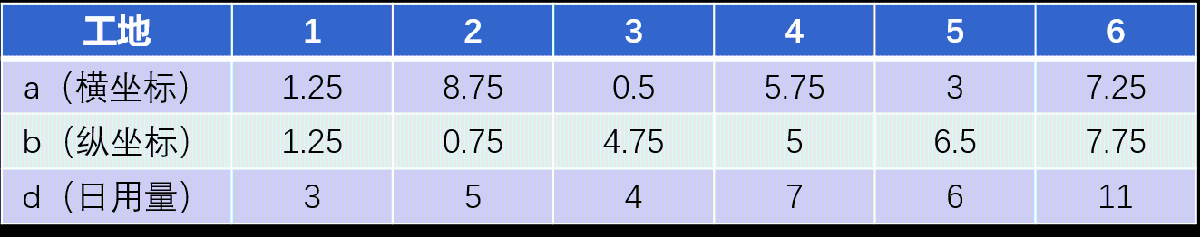

clear;clc;
% 6个工地坐标
a=[1.25 8.75 0.5 5.75 3 7.25];
b=[1.25 0.75 4.75 5 6.5 7.75];
% 临时料场位置
x=[5 2];
y=[1 7];
% 6个工地水泥日用量
d=[3 5 4 7 6 11];
% 计算目标函数系数，即6工地与两个料场的距离，总共12个值
for i=1:6   % 对于6个工地
    for j=1:2       % 接收两个料场的供用
        l(i,j)=sqrt((x(j)-a(i))^2+(y(j)-b(i))^2);   % 距离
    end
end

第一问求解线性规划`：[x,fval]= linprog(f,A,b,Aeq,beq,lb,ub)`

目标函数：


$$\min f=\sum_{j=1}^{2} \sum_{i=1}^{6} X_{i j} \sqrt{\left(x_{j}-a_{i}\right)^{2}+\left(y_{j}-b_{i}\right)^{2}}$$


约束条件：


$$\text { s.t. }\left\{\begin{array}{c}
\sum_{\mathrm{i}=1}^{6} X_{i j} \leq e_{j}, j=1,2 \\
\sum_{j=1}^{2} X_{i j}=d_{i}, i=1,2, \ldots, 6
\end{array}\right.$$


**模型中X共12个值，为方便写代码，设：**


$$X_{11}=X_{1}, X_{21}=X_{2}, X_{31}=X_{3}, \\
X_{41}=X_{4}, X_{51}=X_{5}, X_{61}=X_{6}，\\
X_{12}=X_{7}, X_{22}=X_{8}, X_{32}=X_{9},\\
X_{42}=X_{10}, X_{52}=X_{11},X_{62}=X_{12}$$


**必须清楚这12个变量的实际意义，才能正确写出代码！！！**

f = [l(:,1);l(:,2)];    % 目标函数系数向量，总共12个值

% 不等式约束条件的变量系数和常数项
A = [1 1 1 1 1 1 0 0 0 0 0 0
     0 0 0 0 0 0 1 1 1 1 1 1];    
% 两个临时料场日储量
b = [20;20];

% 矩阵的行数是约束条件个数，列数是变量个数
% 等式约束的变量系数和常数项
Aeq = [eye(6),eye(6)];    % 两个单位矩阵横向拼成
beq=[d(1);d(2);d(3);d(4);d(5);d(6)];
% 所有变量下限全是0
Vlb=[0 0 0 0 0 0 0 0 0 0 0 0]; 
[x,fval]=linprog(f,A,b,Aeq,beq,Vlb);

Optimal solution found.



x,fval

x =      3
     5
     0
     7
     0
     1
     0
     0
     4
     0


fval = 136.2275

# 第二问非线性规划

延续第一问设的${\;X}_1$到${\;X}_{12}$，代表料场到工地的运输水泥量；

第二问要求确定新料场的位置，所以要再添加4个变量，作为两个新料场的横纵坐标.

因此，**第二问有16个变量，设定为**${\;X}_1$**到**${\;X}_{16}$

相应地，每个约束条件的系数矩阵中，也要有16个元素

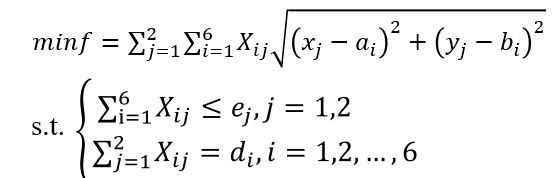

% 注意！第二问中求新料场位置，所以两个料场的横纵坐标也是变量，所以多了4个变量
% 对新坐标没有不等式约束，所以其不等式约束条件里的系数为0
A2 = [1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0
      0 0 0 0 0 0 1 1 1 1 1 1 0 0 0 0];
B2 = [20;20];
% 对新坐标也没有等式约束，所以相应项也为0
Aeq2 = [eye(6),eye(6),zeros(6,4)];    % 两个单位矩阵和一个全0矩阵拼成
beq2=[3 5 4 7 6 11]';
Vlb2=[zeros(12,1);-inf;-inf;-inf;-inf];

非线性规划必须赋初值，可以基于问题情况来设，或设置rand()随机数等等；

初始值设为线性规划的计算结果，即临时料场的坐标

设置初始值x0，此处可直接使用第一问的值作为初始值；

x0=[3 5 0 7 0 1 0 0 4 0 6 10 5 1 2 7]';  
[x2,fval2]=fmincon(@obj_f,x0,A2,B2,Aeq2,beq2,Vlb2)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x2 =     2.9410
    4.8405
    3.8779
    6.9431
    1.3033
    0.0221
    0.0590
    0.1595
    0.1221
    0.0569


fval2 = 90.4920

@obj_f代表调用本文件中定义的函数，一般函数写在文件最后面

**可多设几次不同的初始值求解，选择其中最优的作为最终答案；**

没有适用于所有非线性规划问题的通用解法，所以一般求的都是近似解。

本次使用的matlab自带的fmincon求的就是近似解。

此外，若约束条件里有非线性函数，可使用在fmincon里使用`nonlcon` 项，具体见：

[https://ww2.mathworks.cn/help/optim/ug/fmincon.html?searchHighlight=fmincon&s_tid=srchtitle_fmincon_1#busog7r-nonlcon](https://ww2.mathworks.cn/help/optim/ug/fmincon.html?searchHighlight=fmincon&s_tid=srchtitle_fmincon_1#busog7r-nonlcon)

若有条件，可使用**蒙特卡罗法**求一个近似解作为初始值

1、因为第2问模型中有16个变量，所以要给16个变量分别生成随机值，作为当前解；

2、判断这些当前解是否满足模型的约束条件

3、若满足，代入目标函数，求当前目标函数值

4、判断当前目标函数值是否比已求的较优函数值更好，若是，则替换掉较优函数值和对应的较优解

5、不断重复前5步，构成统计意义，求得较优解。


p0 = 10000; n = 10^6; tic
x_m0 = 0;
for i = 1:n
    % 前12个数是6个工地从两个料场接收的量，6个工地分别需要3,5,4,7,6,11吨水泥
    % 所以前12个变量分别需要取0到3，0到5，……，0到11的随机数
    % 为加速求近似，取前12个变量（工地从料场接受的量）为随机整数
    % randi(n)为随机取1到n之间的一个整数，则randi(n+1)-1为取0到n间随机整数
    % 后4个变量是两个料场的横纵坐标，取一定范围内的随机数（根据题目，工地坐标都在0到9，所以此处取0到9）
    x_m = [randi(4)-1,randi(6)-1,randi(5)-1,randi(8)-1,randi(7)-1,randi(12)-1,...
        randi(4)-1,randi(6)-1,randi(5)-1,randi(8)-1,randi(7)-1,randi(12)-1,...
        9*rand(1,4)];
    
    [g,k] = constraint(x_m);        % 约束条件
    if all(g<=0)   % 等式约束难以严格满足，所以此处相差不大即可算近似
        if all(abs(k)<=1)
            ff = obj_f(x_m);     % 目标函数
            if ff<p0
                x_m0 = x_m; p0 = ff;
            end
        end
    end
  
end
x_m0,p0,toc

x_m0 =     3.0000    3.0000    1.0000    7.0000    5.0000         0         0    1.0000    2.0000         0         0   10.0000    4.0732    6.4004    7.5229    8.7223


p0 = 98.5436

历时 3.656380 秒。


% 以采样10^6次的蒙特卡罗法求得的近似值作为初始值，调用fmincon
[x3,fval3]=fmincon(@obj_f,x_m0,A2,B2,Aeq2,beq2,Vlb2)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x3 =     2.9733    0.1790    3.9764    6.5729    5.9696    0.0207    0.0267    4.8210    0.0236    0.4271    0.0304   10.9793    3.2206    5.6670    7.2500    7.7500


fval3 = 85.9492

% 此时最终求得的结果fval3 = 85.4054，
% 优于前面以第一问线性规划结果为初始值时求得的90.4920
% 注意！！！非线性规划每次求解的结果都不一样！！！
% 多次运行相同代码，得出的结果不相同是正常的！！！

目标函数和约束条件，以函数的形式计算

function ff = obj_f(x)   
% 6个工地坐标
a1 = [1.25 8.75 0.5 5.75 3 7.25];
b1 = [1.25 0.75 4.75 5 6.5 7.75];

f1=0;

% x(13)是第一个新料场的横坐标，x(14)是其纵坐标；
% x(15)是第二个新料场的横坐标，x(16)是其纵坐标；
for i=1:6
    s(i)=sqrt((x(13)-a1(i))^2+(x(14)-b1(i))^2); % 第一个料场到各工地的距离
    f1=s(i)*x(i)+f1;  % 第一个料场给各工地的吨千米数
end

f2=0;

for i=7:12
    s(i)=sqrt((x(15)-a1(i-6))^2+(x(16)-b1(i-6))^2);  % 第二个料场到各工地的距离
    f2=s(i)*x(i)+f2;  % 第二个料场给各工地的吨千米数
end
% 总运输量（吨千米数）
ff=f1+f2;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 约束条件计算式，供蒙特卡罗法使用
function [g,k] = constraint(x)
% 不等式约束条件
% sum(x(:,1:6),2)是对矩阵前6列按行求和，即对前6个元素求和，
% 对应6个工地接收第一个料场的总量。再减去20，即把不等式右边常数项移到左边
g = [sum(x(:,1:6),2)-20    
     sum(x(:,7:12),2)-20
    ];
% 等式约束条件,6个工地从两个料场收到的总量分别为3,5,4,7,6,11
k = [x(1)+x(7)-3
     x(2)+x(8)-5
     x(3)+x(9)-4
     x(4)+x(10)-7
     x(5)+x(11)-6
     x(6)+x(12)-11
    ];
end

% 本文件出自b站/公众号：数学建模BOOM
% 关注微信公众号：数学建模BOOM，回复"课程"
% 查看全套视频课程+配套PPT课件+代码文件